# Recursive Watermark visualisation script

April 2020

## Simulaiton intiialization

% length of the simulation
t_sim=1000;


## RWM initialization

Seed=123;
mu=0.2;
Nq=1024;% quantiation level
N0=1;
dictionry_legth = 1000;
% Nc=50 % reset every 50 cycles - not used

Initialise hashing dictionary

rng(Seed) % pseudo rand
Hf=rand(dictionry_legth,1);
% Hashing Dictionary
HashR=rand(dictionry_legth,1);

## Attack parameters 

AttTime = 400;
AttType = 'delay'; 
% AttType = 'inject';


## Original signal

t = linspace(1,5*pi,t_sim)';
% Simple
%S=sin(t); 
% More demanding
S=sin(t)+cos(2*t) + [2*ones(t_sim/2,1); transpose(linspace(2,-2,t_sim/4)) ;-2*ones(t_sim/4,1)];

## Signal watermarking

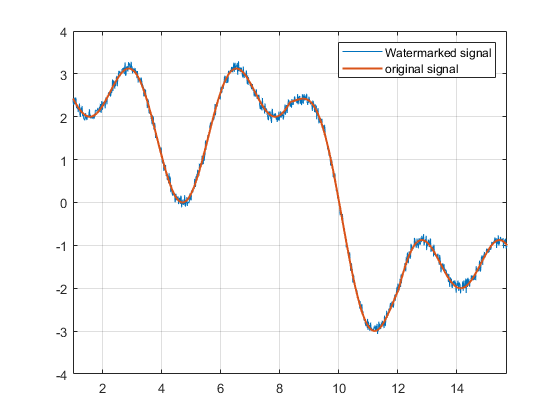

Vsf=S+mu*Hf; %V = S+Hf*mu
Vsfr=zeros(length(S),1);
Vsfr(1)=S(1);
% Vsfr(2:end)=Vsf(2:end)+mu*HashPM1(Vsf(1:end-1), HashR); % scaling factor
% must be the same!
%  %V = S+Hf*mu+Hr*mu
for idx=2:t_sim
    Vsfr(idx)=S(idx)+mu*Hf(idx)+mu*HashPM1(Vsfr(idx-1), HashR) - mu;
end
clf
figure(2);
plot(t,Vsfr);
hold on; grid on
plot(t,S,'LineWidth',1.5);
xlim([t(1),t(end)])
legend('Watermarked signal','original signal')

## Man in the midle attack

% injection attack
AttInjection = Vsfr + [0*ones(AttTime,1); transpose(linspace(0,5,t_sim/4)) ; 5*ones(t_sim-t_sim/4-AttTime,1)]; 

% Time delay (Replay) attack
AttDelay = [Vsfr(1:AttTime); Vsfr(AttTime); Vsfr(AttTime+1:end-1)];

% Choose the attack
if strcmp(AttType, 'delay')
    Vhack1=AttDelay; 
elseif strcmp(AttType, 'inject')
    Vhack1=AttInjection; 
else
    Vhack1= Vsfr;
end

## Recovery without attack

Shat=zeros(length(Vsfr),1);
% Reset point
Shat(1)=Vsfr(1);
for idx=2:t_sim
    Shat(idx)=Vsfr(idx)-mu*Hf(idx)-mu*HashPM1(Vsfr(idx-1), HashR)+mu;
end
Sdiff=Shat-S;

## Recovery with attack

Shat_hack1=zeros(length(Vhack1),1);
% Reset point
Shat_hack1(1)=Vhack1(1);
for idx=2:t_sim
    Shat_hack1(idx)=Vhack1(idx)-mu*Hf(idx)-mu*HashPM1(Vhack1(idx-1), HashR) + mu;
end
Sdiff_hack1=Shat_hack1-S;

## Chi^2 square test calculation

chi2test=[0];
% Chi square test
clear Y Y_attack n 
for idx=2:t_sim
    chi2test(idx)=chi_2(Shat_hack1(idx),Shat_hack1(idx-1));
end

## Displaying results

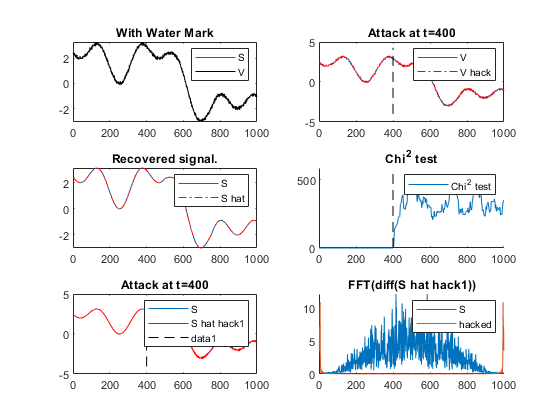

close all;
subplot(3,2,1)
plot(S);
hold on;
plot(Vsfr, 'k');
% legend('S', 'S+Hf', 'S+Hf+Hr');
legend('S', 'V')
title('With Water Mark');

subplot(3,2,2)
plot(Vsfr);
hold on;
plot(Vhack1, '-.r');
plot([AttTime AttTime],[1.3*min([Vsfr; Vhack1]) 1.3*max([Vsfr; Vhack1])],'k--')
legend('V', 'V hack');
title(strcat('Attack at t=',num2str(AttTime)));

subplot(3,2,3)
% recover
plot(S);
hold on;
plot(Shat,'-.r');
legend('S', 'S hat');
title('Recovered signal.');

% subplot(3,2,4)
% % plot(abs(fft(Shat)));
% plot(abs(fft(diff(Shat))));
% title('FFT(diff (S hat) )')

subplot(3,2,4)
% plot(abs(fft(Shat)));
hold on
plot(chi2test);
plot([AttTime AttTime],[0 1.2*max(chi2test)],'k--')
title('Chi^{2} test')
legend('Chi^{2} test');

subplot(3,2,5)
h1=plot(S);
hold on;
h2=plot(Shat_hack1, 'r');
legend([h1, h2], 'S', 'S hat hack1');
plot([AttTime AttTime],[1.3*min([Shat_hack1; S]) 1.3*max([Shat_hack1; S])],'k--')
title(strcat('Attack at t=',num2str(AttTime)));

subplot(3,2,6)
% plot(abs(fft(Shat_hack1)));
hold on
h1=plot(abs(fft(diff(Shat_hack1))));
h2=plot(abs(fft(diff(Shat))));
legend([h1,h2],'S', 'hacked');
title('FFT(diff(S hat hack1))')

## Correlation properties

A=[Hf S];
disp('Raw data')

Raw data


cor=corrcoef(A)

cor =     1.0000   -0.0041
   -0.0041    1.0000


A0=[Hf Vsfr];
disp('Noise')

Noise


cor0=corrcoef(A0)

cor0 =     1.0000    0.0253
    0.0253    1.0000


A1=[Hf Shat];
A2=[Hf Shat_hack1];
disp('No attack')

No attack


cor1=corrcoef(A1)

cor1 =     1.0000   -0.0041
   -0.0041    1.0000


disp('With delay attack')

With delay attack


cor2=corrcoef(A2)

cor2 =     1.0000   -0.0221
   -0.0221    1.0000


## Simplified Hashing function

function y = HashPM1(in, hash_dict)
% dictionary length
dict_len=length(hash_dict);
y = zeros(size(in));
% Simple index search 
% Signal bounded on [-10,10]
idx_dict = mod(round((in+10)/20 * dict_len),dict_len)+1;
y = hash_dict(idx_dict);
end

## Chi^2 test function

function [gk_chi] = chi_2(y,y_attack) 
persistent Y Y_attack n 
% time-window length
window =50;
% variance of the noise - amplification
Variance = 10e-3;
if isempty(Y)
    n = 0;
    Y = zeros(window,1);
    Y_attack = zeros(window,1);
else
    if(n > 2)
        % simple system dynamics compensation
        dY = Y(1)-Y(2);
        %dY = 0;
    else
        dY = 0;
    end
    % Buffering signal
    Y = [y; Y(1:end-1)];
    Y_attack = [y_attack+dY; Y_attack(1:end-1)];
    n=n+1;
end
% test calculation
gk_chi = sum((Y-Y_attack).*Variance^-1.*(Y-Y_attack));
end